%% Import Data

clc;
clear;
solarData = readtable('SolarData2.csv');


t1 = solarData.sunriseN;   % Sunrise times (t1) in hours, array
t2 = solarData.sunsetN;    % Sunset times (t2) in hours, array
S = solarData.solarE; % Solar Irradiance (S) in W/m²

%% Define Values

A = 2000;          % Panel Area in m²
x_deg = 30;        % Panel Angle in degrees

efficiency = 0.20 %realistic efficiency of commerical solar panel

efficiency = 0.2000

%% Additional Conversions and Array Creation

x_rad = deg2rad(x_deg);  % Convert angle to radians for computation
cos_x = cos(x_rad);      % Cosine of the angle

numDays = length(t1); % Number of days
time_plot = zeros(numDays, 1); %Time array for graphy plot

E = zeros(numDays, 1); % Energy generated each day in kWh

%% Single Calculation for Verification


S_single = 540;
A_single = 80;

f = @(t) cos(pi * (t - 12) / 12);  % Define the function
integralCalc = integral(f, 7, 19);  % Integrate from 0 to 5
E = S_single*A_single*integralCalc;
E_solar_single = E*0.2;
E_solar_single_kWhr = E_solar_single/1000

E_solar_single_kWhr = 63.7557

%% High Level Rough Calc

S_HL = 1044.7; %in kWhr

totalE_HL_Year = S_HL*A*efficiency

totalE_HL_Year = 417880



shading_reduction = 0.85;

totalE_shadow_year = S_HL*A*(efficiency*shading_reduction)

totalE_shadow_year = 355198

%% High Level Rough Calc Additional Solar Roof

S_HL = 1044.7; %in kWhr

E_Ideal_SR = S_HL*500*efficiency

E_Ideal_SR = 104470

%% High Level Solar Wall

efficiency_Wall = 0.18;

E_Ideal_SW = S_HL*(10*11.5)*efficiency_Wall

E_Ideal_SW = 2.1625e+04

%% Daily Solar Generation
z=1;
%Solar irradiance in w/m^2
HourlySolarIrradiance = zeros(365,24);
DailyData = readtable('Daily Data.csv');
dsInput = DailyData.irradiance; %1D list of all values

for x = 1:365
     for y = 1:24
         %Solar irradiance in w/m^2
        HourlySolarIrradiance(x, y) = dsInput(z)*0.7; %Putting into 2D Array
        z = z + 1;
     end
    y = 1;
end

%Standard 20%? Solar panel efficiency 

%Putting each hour into kWh/m^2 using w/m^2 * m^2 /1000
HourlySolarEnergy = (HourlySolarIrradiance*efficiency*A)/1000;

%Summing over 24 hour period for each day
DailySolarEnergy = sum(HourlySolarEnergy,2);

%Total energy sanity check
AnnualSolarEnergy = sum(DailySolarEnergy)

AnnualSolarEnergy = 3.4906e+05

%Alternate Panel Types Calc

%Best efficiencies at single sun

%Crystalline Silicon - Have taken "single" efficiency
CrySilEfficiency = 0.267;
CrySilHourlySolarEnergy = (HourlySolarIrradiance*CrySilEfficiency*A)/1000;
CrySilDailySolarEnergy = sum(CrySilHourlySolarEnergy,2);
CrySilAnnualSolarEnergy = sum(CrySilDailySolarEnergy)

CrySilAnnualSolarEnergy = 4.6600e+05


%Gallium Arsenide (GaAs) - Have taken "single" efficiency
GaAsEfficiency = 0.278;
GaAsHourlySolarEnergy = (HourlySolarIrradiance*GaAsEfficiency*A)/1000;
GaAsDailySolarEnergy = sum(GaAsHourlySolarEnergy,2);
GaAsAnnualSolarEnergy = sum(GaAsDailySolarEnergy)

GaAsAnnualSolarEnergy = 4.8520e+05


%Two Junction
TwoJuncEfficiency = 0.328;
TwoJuncHourlySolarEnergy = (HourlySolarIrradiance*TwoJuncEfficiency*A)/1000;
TwoJuncDailySolarEnergy = sum(TwoJuncHourlySolarEnergy,2);
TwoJuncAnnualSolarEnergy = sum(TwoJuncDailySolarEnergy)

TwoJuncAnnualSolarEnergy = 5.7246e+05


%Three Junction
ThreeJuncEfficiency = 0.379;
ThreeJuncHourlySolarEnergy = (HourlySolarIrradiance*ThreeJuncEfficiency*A)/1000;
ThreeJuncDailySolarEnergy = sum(ThreeJuncHourlySolarEnergy,2);
ThreeJuncAnnualSolarEnergy = sum(ThreeJuncDailySolarEnergy)

ThreeJuncAnnualSolarEnergy = 6.6147e+05


%Four Junction
FourJuncEfficiency = 0.392;
FourJuncHourlySolarEnergy = (HourlySolarIrradiance*FourJuncEfficiency*A)/1000;
FourJuncDailySolarEnergy = sum(FourJuncHourlySolarEnergy,2);
FourJuncAnnualSolarEnergy = sum(FourJuncDailySolarEnergy)

FourJuncAnnualSolarEnergy = 6.8416e+05


%Cadmium Telluride (CdTe)
CdTeEfficiency = 0.221;
CdTeHourlySolarEnergy = (HourlySolarIrradiance*CdTeEfficiency*A)/1000;
CdTeDailySolarEnergy = sum(CdTeHourlySolarEnergy,2);
CdTeAnnualSolarEnergy = sum(CdTeDailySolarEnergy)

CdTeAnnualSolarEnergy = 3.8571e+05


%Organic
OrganicEfficiency = 0.165;
OrganicHourlySolarEnergy = (HourlySolarIrradiance*OrganicEfficiency*A)/1000;
OrganicDailySolarEnergy = sum(OrganicHourlySolarEnergy,2);
OrganicAnnualSolarEnergy = sum(OrganicDailySolarEnergy)

OrganicAnnualSolarEnergy = 2.8798e+05


%Perovskite
PerovskiteEfficiency = 0.252;
PerovskiteHourlySolarEnergy = (HourlySolarIrradiance*PerovskiteEfficiency*A)/1000;
PerovskiteDailySolarEnergy = sum(PerovskiteHourlySolarEnergy,2);
PerovskiteAnnualSolarEnergy = sum(PerovskiteDailySolarEnergy)

PerovskiteAnnualSolarEnergy = 4.3982e+05


%Perovskite/SI Tandem
SIPerovskiteEfficiency = 0.280;
SIPerovskiteHourlySolarEnergy = (HourlySolarIrradiance*SIPerovskiteEfficiency*A)/1000;
SIPerovskiteDailySolarEnergy = sum(SIPerovskiteHourlySolarEnergy,2);
SIPerovskiteAnnualSolarEnergy = sum(SIPerovskiteDailySolarEnergy)

SIPerovskiteAnnualSolarEnergy = 4.8869e+05

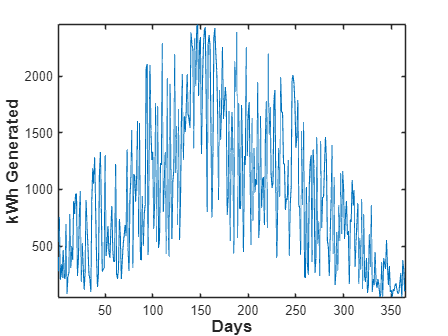

%Plotting pretty graph
days = 1:365;

figure;
plot(days,DailySolarEnergy,'Linewidth',1);
axis tight; % Fit the axis to the data tightly

% Font Style and Size
set(gca, 'FontSize', 12, 'FontName', 'Arial'); % Adjust font for axes
xlabel('Days', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('kWh Generated', 'FontSize', 16, 'FontWeight', 'bold');

%% Plot of solar variation across a given days
% i.e. winter solstice, summer solstice, spring equipnox and FALL equinox
HoursInDay = 1:24;

wintersolstice = HourlySolarEnergy(355,:);
summersolstice = HourlySolarEnergy(171,:);
springeq = HourlySolarEnergy(81,:);
autumneq = HourlySolarEnergy(265,:);

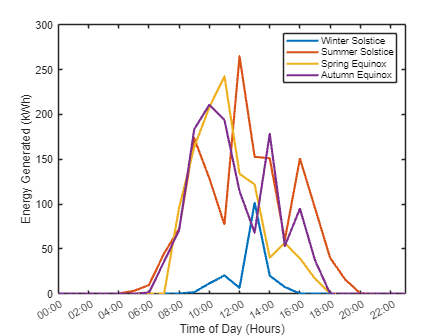

% Plotting pretty solstice graphs
figure;

hold on
plot(HoursInDay,wintersolstice, linewidth = 2)
plot(HoursInDay,summersolstice, linewidth = 2)
plot(HoursInDay,springeq, linewidth = 2)
plot(HoursInDay,autumneq, linewidth = 2)
hold off

%set(gca, 'FontSize', 12, 'FontName', 'Arial'); % Adjust font for axes
%ylabel('Energy Generated (kWh)','FontSize', 12, 'FontWeight', 'bold');
%xlabel('Hours','FontSize', 12, 'FontWeight', 'bold')
%fontsize(gca,24,"pixels");
ylabel('Energy Generated (kWh)')%,FontSize=28);
xlabel("Time of Day (Hours)")%,FontSize=28)
times = hours(0:23);
timeStrings = string(datetime(2024,1,1) + times, 'HH:mm');
xticks(1:2:length(timeStrings));
xlim([1,24])
xticklabels(timeStrings(1:2:end));
%title('Daily Solar Energy Generation, Seasonal');
legend('Winter Solstice', 'Summer Solstice', 'Spring Equinox', 'Autumn Equinox')
box on

ax = gca;
exportgraphics(ax,'DailySolar.eps','Resolution',300) 

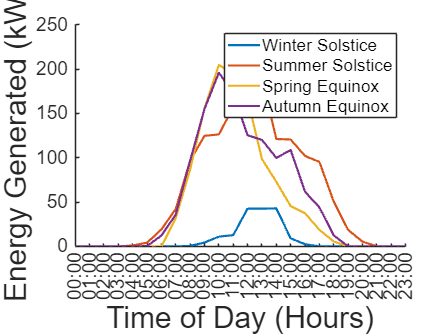

%% Plotting smoother solstice graphs

% Define the hours
HoursInDay = 1:24;

% Your daily irradiance data
wintersolstice = HourlySolarEnergy(355,:);
summersolstice = HourlySolarEnergy(171,:);
springeq = HourlySolarEnergy(81,:);
autumneq = HourlySolarEnergy(265,:);

% Smoothing the data using a moving average
window_size = 2.5; % Adjust this as needed

smoothed_wintersolstice = movmean(wintersolstice, window_size);
smoothed_summersolstice = movmean(summersolstice, window_size);
smoothed_springeq = movmean(springeq, window_size);
smoothed_autumneq = movmean(autumneq, window_size);

% Plotting
figure;
hold on
plot(HoursInDay, smoothed_wintersolstice, 'LineWidth', 2);
plot(HoursInDay, smoothed_summersolstice, 'LineWidth', 2);
plot(HoursInDay, smoothed_springeq, 'LineWidth', 2);
plot(HoursInDay, smoothed_autumneq, 'LineWidth', 2);
hold off

% Labels and legend
fontsize(gca,24,"pixels");
ylabel('Energy Generated (kWh)',FontSize=28);
xlabel("Time of Day (Hours)",FontSize=28)
times = hours(0:23);
timeStrings = string(datetime(2024,1,1) + times, 'HH:mm');
xticks(1:length(timeStrings));
xlim([1,24])
xticklabels(timeStrings);
%title('Daily Solar Energy Generation, Seasonal');
legend('Winter Solstice', 'Summer Solstice', 'Spring Equinox', 'Autumn Equinox');

% Putting array into pretty table format and saving for use in intergrated
% models file

startDate = datetime('2023-01-01');
endDate = datetime('2023-12-31');
dates = startDate:endDate;

% Get full day names
dayNames = string(day(dates, 'name')); % 'dddd' gives full day names

% Create time strings (optional, if needed for another purpose)
times = hours(0:23);
timeStrings = string(datetime(2023,1,1) + times, 'HH:mm');  % Create datetime starting from a base date

% Preallocate the VarNames cell array
VarNames = cell(1, length(dates));

% Loop through each date and create formatted strings
for i = 1:length(dates)
    VarNames{i} = sprintf('%s: %s', datestr(dates(i), 'dd-mmm-yyyy'), dayNames(i));
end

BasicHourlySolarEnergy = array2table(HourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
CrySilHourlySolarEnergy = array2table(CrySilHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
GaAsHourlySolarEnergy = array2table(GaAsHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
TwoJuncHourlySolarEnergy = array2table(TwoJuncHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
ThreeJuncHourlySolarEnergy = array2table(ThreeJuncHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
FourJuncHourlySolarEnergy = array2table(FourJuncHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
CdTeHourlySolarEnergy = array2table(CdTeHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
OrganicHourlySolarEnergy = array2table(OrganicHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
PerovskiteHourlySolarEnergy = array2table(PerovskiteHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
SIPerovskiteHourlySolarEnergy = array2table(SIPerovskiteHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));

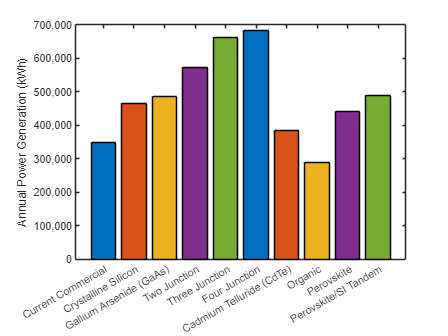

% Plot colours: 
colours = [[0 0.4470 0.7410],
    [0.8500 0.3250 0.0980],
    [0.9290 0.6940 0.1250],
    [0.4940 0.1840 0.5560],
    [0.4660 0.6740 0.1880],
    [0.3010 0.7450 0.9330],
    [0.6350 0.0780 0.1840]];


% Solar Plot of different types of panel

figure;
x = ["Current Commercial", ...
    "Crystalline Silicon", ...
    "Gallium Arsenide (GaAs)", ...
    "Two Junction", ...
    "Three Junction", ...
    "Four Junction", ...
    "Cadmium Telluride (CdTe)", ...
    "Organic", ...
    "Perovskite", ...
    "Perovskite/SI Tandem"];
y = table2array([sum(BasicHourlySolarEnergy,"all")
    sum(CrySilHourlySolarEnergy,"all")
    sum(GaAsHourlySolarEnergy,"all")
    sum(TwoJuncHourlySolarEnergy,"all")
    sum(ThreeJuncHourlySolarEnergy,"all")
    sum(FourJuncHourlySolarEnergy,"all")
    sum(CdTeHourlySolarEnergy,"all")
    sum(OrganicHourlySolarEnergy,"all")
    sum(PerovskiteHourlySolarEnergy,"all")
    sum(SIPerovskiteHourlySolarEnergy,"all")
    ]);
hold on
b = bar(x,y,'BarWidth', 0.8);

cols=zeros(length(x),3);

for i=1:5
    cols(i,:) = colours(i,:);
    cols(i+5,:) = colours(i,:);
end
b.FaceColor = 'flat';
b.CData = cols;

%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
box on
ytickformat('%,.0f')
ylabel("Annual Power Generation (kWh)")%),FontSize=28);
ax = gca;
exportgraphics(ax,'SolarPanelTypes.eps','Resolution',300) 

% For whole system model:


%Solar Roof Calc
RoofEfficiency = 0.23;
ARoof = A;
RoofHourlySolarEnergy = (HourlySolarIrradiance*RoofEfficiency*A)/1000;
RoofDailySolarEnergy = sum(RoofHourlySolarEnergy,2);
RoofAnnualSolarEnergy = sum(RoofDailySolarEnergy)

RoofAnnualSolarEnergy = 4.0142e+05


%Solar Quad calc
QuadEfficiency = 0.23;
AQuad = 500;
QuadHourlySolarEnergy = (HourlySolarIrradiance*QuadEfficiency*AQuad)/1000;
QuadDailySolarEnergy = sum(QuadHourlySolarEnergy,2);
QuadAnnualSolarEnergy = sum(QuadDailySolarEnergy)

QuadAnnualSolarEnergy = 1.0036e+05


%Solar Wall calc
WallEfficiency = 0.18;
AWall = 10*11.5;
WallHourlySolarEnergy = (HourlySolarIrradiance*WallEfficiency*AWall)/1000;
WallDailySolarEnergy = sum(WallHourlySolarEnergy,2);
WallAnnualSolarEnergy = sum(WallDailySolarEnergy)

WallAnnualSolarEnergy = 1.8064e+04



RoofHourlySolarEnergy = array2table(RoofHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
QuadHourlySolarEnergy = array2table(QuadHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));
WallHourlySolarEnergy = array2table(WallHourlySolarEnergy','RowNames',string(timeStrings),'VariableNames',string(VarNames));


save("../SolarVariables.mat", "RoofHourlySolarEnergy", ...
    "QuadHourlySolarEnergy", ...
    "WallHourlySolarEnergy");